### TOY EXAMPLE - MS PAINT IMAGE (16x16)

#### A toy image

#### 1. Image as matrix and vector

#### 2. Forward model: y = A*x + noise

#### 3. Pseudoinverse reconstruction (FAILS)

#### 4. Why it fails: singular value decay

clear; clc; close all;

#### 1. Load Image (16x16)

image_path = 'toy16x16.png'; 
img = imread(image_path);

% Convert to grayscale
if ndims(img) == 3
    img = mean(double(img), 3);
else
    img = double(img);
end

% Normalize
x = img / max(img(:));

n = size(x, 1);
fprintf('Image shape: %d x %d\n', n, n);

Image shape: 16 x 16


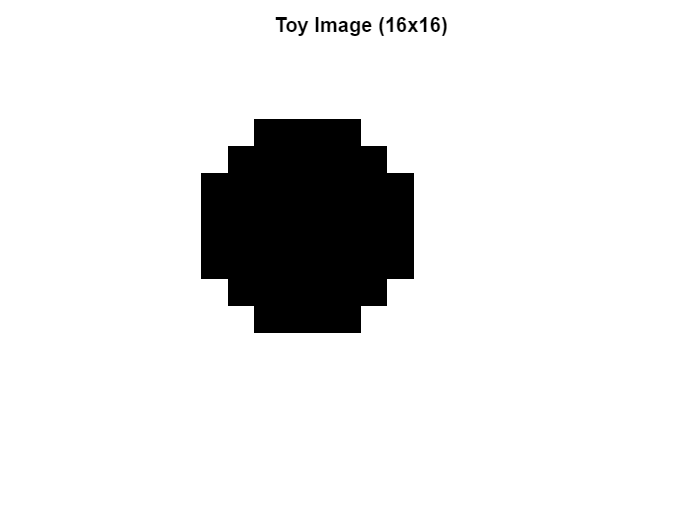


% Display original image
figure;
imagesc(x);
colormap gray;
axis image off;
title(sprintf('Toy Image (%dx%d)', n, n));

#### 2. Pixels Visualization

fprintf('\nPixel values (matrix form):\n');


Pixel values (matrix form):


disp(round(x, 2));

     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     0     0     0     0     1     1     1     1     1     1     1     1
     1     1     1     0     0     0     0     0     0     1     1     1     1     1     1     1
     1     1     0     0     0     0     0     0     0     0     1     1     1     1     1     1
     1     1     0     0     0     0     0     0     0     0     1     1     1     1     1     1
     1     1     0     0     0     0     0     0     0     0     1     1     1     1     1     1
     1     1     0     0     0     0     0     0     0     0     1     1     1     1     1     1
     1     1     1     0     0     0     0     0     0     1     1     1     1     1     1     1
     1     1     1     1     0

#### 3. Image as Vector

x_vec = x(:);  
fprintf('Vectorized image shape: %d x 1\n', length(x_vec));

Vectorized image shape: 256 x 1


#### 4. Define Gaussian Blur Kernel

kernel_size = 7;
sigma = 1.5;

half_size = floor(kernel_size / 2);
[xx, yy] = meshgrid(-half_size:half_size, -half_size:half_size);
kernel = exp(-(xx.^2 + yy.^2) / (2 * sigma^2));
kernel = kernel / sum(kernel(:));

fprintf('\nKernel size: %d x %d\n', size(kernel, 1), size(kernel, 2));


Kernel size: 7 x 7


#### 5. Build Explicit Blur Matrix A

N = n * n;
A = zeros(N, N);

for i = 1:N
    basis = zeros(n, n);
    basis(i) = 1.0;
    blurred = imfilter(basis, kernel, 'symmetric', 'same');
    A(:, i) = blurred(:);
end

fprintf('Matrix A shape: %d x %d\n', size(A, 1), size(A, 2));

Matrix A shape: 256 x 256


#### 6. Forward Model: y = A*x + noise

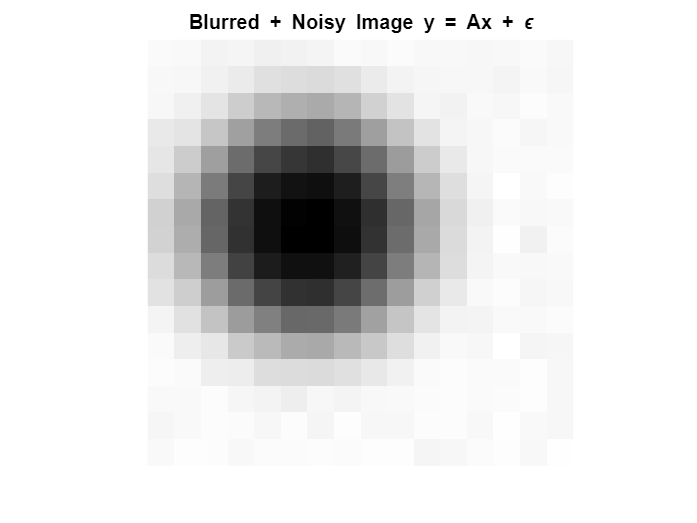

Ax = A * x_vec;
noise_level = 0.01;
noise = noise_level * randn(size(Ax));

y = Ax + noise;
y_img = reshape(y, [n, n]);

figure
imagesc(y_img);
colormap gray;
axis image off;
title('Blurred + Noisy Image y = Ax + \epsilon');

#### 7. Naive Inversion Using Pseudoinverse

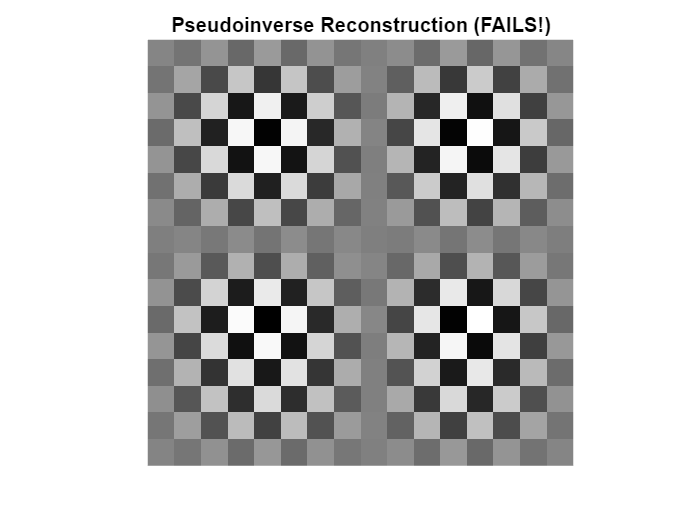

[U, S_mat, V] = svd(A, 'econ');
S = diag(S_mat); 

% Pseudoinverse reconstruction
S_inv = diag(1.0 ./ S);
x_pinv = V * S_inv * U' * y;
x_pinv_img = reshape(x_pinv, [n, n]);

figure;
imagesc(x_pinv_img);
colormap gray;
axis image off;
title('Pseudoinverse Reconstruction (FAILS!)');

#### 8. Singular Value Decay (WHY It Fails)

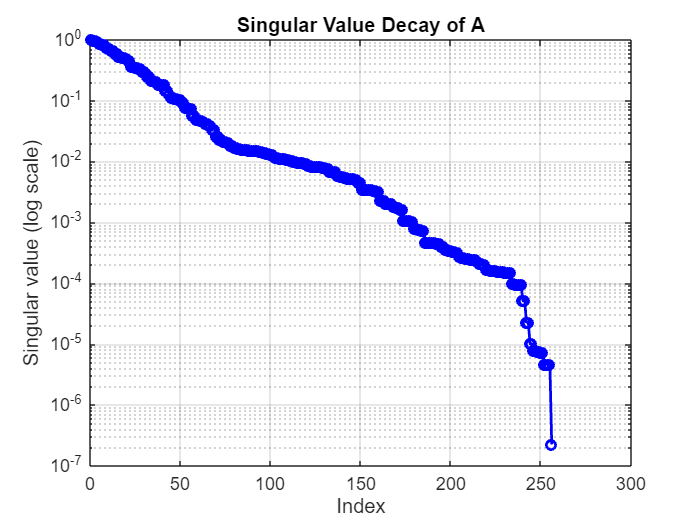

figure;
semilogy(S, 'b-o', 'LineWidth', 1.5, 'MarkerSize', 5);
xlabel('Index');
ylabel('Singular value (log scale)');
title('Singular Value Decay of A');
grid on;


condition_number = S(1) / S(end);
fprintf('\nCondition number of A: %.2e\n', condition_number);


Condition number of A: 4.45e+06


#### 9. Analysis

rel_error = norm(x_pinv - x_vec) / norm(x_vec);
fprintf('Relative reconstruction error: %.4f (%.1f%%)\n', rel_error, rel_error*100);

Relative reconstruction error: 2557.7191 (255771.9%)


fprintf('Noise level used: %.4f\n', noise_level);

Noise level used: 0.0100


fprintf('Condition number: %.2e\n', condition_number);

Condition number: 4.45e+06


fprintf('\n Small singular values amplify noise by factor ~%.0f! \n', condition_number);


 Small singular values amplify noise by factor ~4454780! 
